# Examine Well-Trained Session using Temporal Field Bayes - True-Correct Temporal vs Ordinal Coding

fileDirs = [{'D:\WorkBigDataFiles\PFC\GE11_Session132'},...
    {'D:\WorkBigDataFiles\PFC\GE13_Session083'},...
    {'D:\WorkBigDataFiles\PFC\GE14_Session123'},...
    {'D:\WorkBigDataFiles\PFC\GE17_Session095'},...
    {'D:\WorkBigDataFiles\PFC\GE24_Session096'}];

binSize = 200;
dsRate = 50;
trlWindow = {[-800 2000]};
alignment = {'PokeIn'};
% trlWindow = {[-2000 800]};
% alignment = {'PokeOut'};
bayesType = 1; 
%bayseTypes: 1 = Poisson: use with raw spike counts; 2 = Bernoulli: use with binarized spike counts; 3 = Gaussian: Use with z-scored spike counts

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

%#ok<*UNRCH>


## Compile Data

tic;
for ani = 1:length(fileDirs)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Behavior Variables
        fiscPokeOutLat = cell(length(fileDirs),1);
        fiscRwdDelivLat = cell(length(fileDirs),1);
        % Posteriors
        realPost = cell(mlb.seqLength, 1, length(fileDirs));
    end
    mlb.binSize = binSize;
    mlb.dsRate = dsRate;
    mlb.windows = trlWindow;
    mlb.alignments = alignment;
    mlb.bayesType = bayesType;
    
    fiscPokeOutLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeOutIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    fiscRwdDelivLat{ani} = ([mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).RewardIndex] - [mlb.trialInfo(mlb.fiscTrials(~isnan(mlb.fiscTrials))).PokeInIndex])'/1000;
    
    % Process Observations - FISC via Leave-1-Out
    mlb.SetLikes_FISC;
    mlb.Process_LikelyL1O;
    realPost(:,1,ani) = mlb.post;      
end

Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed


pokeOutLats = cell2mat(fiscPokeOutLat(:));
nearestPOtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(pokeOutLats),1,'last'));
rwdDelivLat = cell2mat(fiscRwdDelivLat(:));
nearestRWDtime = mlb.obsvTimeVect(find(mlb.obsvTimeVect<median(rwdDelivLat),1,'last'));
piNdx = find(mlb.likeTimeVect==0)+0.5;
poNdx = find(mlb.likeTimeVect==nearestPOtime)+0.5;
rwdNdx = find(mlb.likeTimeVect==nearestRWDtime)+0.5;
posNdx = find(diff(mlb.likeTimeVect)<0)+0.5;
toc

Elapsed time is 31.706985 seconds.


## Combine trials across animals & compute True-Correct marginals

tic;
numSeqs = size(cell2mat(realPost(1,1,:)),3);
netSize = 1;
groupPost = cell(mlb.seqLength,1);
groupPos = cell(mlb.seqLength,1);
groupTime = cell(mlb.seqLength,1);
tpCorr = cell(mlb.seqLength,1);
for pos = 1:mlb.seqLength
    groupPost{pos} = cell2mat(realPost(pos,:,:));
    tempPosDecodes = mlb.TabulateBayesPost(groupPost{pos}, mlb.decodeIDvects(:,3));
    groupPos{pos} = squeeze(tempPosDecodes(:,pos,:));
    tempTimeDecodes = mlb.TabulateBayesPost(groupPost{pos}, mlb.decodeIDvects(:,1));
    tempDiag = nan(length(mlb.obsvTimeVect), numSeqs);
    for s = 1:numSeqs
        for t = 1:length(mlb.obsvTimeVect)
            if t == 1
                tempVals = tempTimeDecodes(t:t+netSize,t:t+netSize,s);
            elseif t-netSize<1
                tempVals = tempTimeDecodes(1:t+netSize, 1:t+netSize,s);
            elseif t == length(mlb.obsvTimeVect)
                tempVals = tempTimeDecodes(t-netSize:t,t-netSize:t,s);
            elseif t+netSize>length(mlb.obsvTimeVect)
                tempVals = tempTimeDecodes(t-netSize:end,t-netSize:end,s);
            else
                tempVals = tempTimeDecodes(t-netSize:t+netSize,t-netSize:t+netSize,s);
            end
            tempDiag(t,s) = mean(tempVals(:));
        end
    end
    groupTime{pos} = tempDiag;
    [r,p] = corr(groupPos{pos},groupTime{pos});
    tpCorr{pos} = [r(:,1), p(:,1)];
end
toc

Elapsed time is 1.121304 seconds.


## Plot Time & Position Coding Correlational Strength

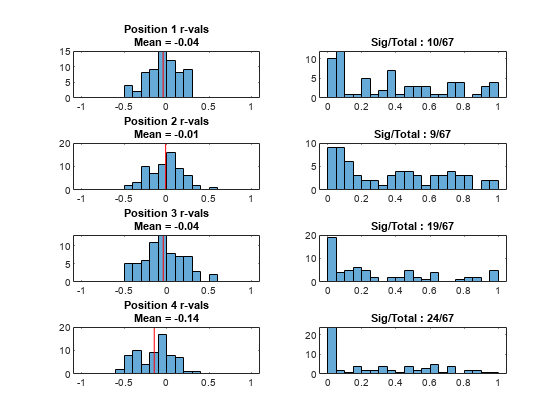

figure
posID = cell(size(tpCorr));
for pos = 1:mlb.seqLength
    posID{pos} = zeros(size(tpCorr{pos},1),1)+pos;
    subplot(mlb.seqLength,2,sub2ind([2,mlb.seqLength],1,pos));
    histogram(tpCorr{pos}(:,1), -1:0.1:1);
    title([{sprintf('Position %i r-vals',pos)};{sprintf('Mean = %.02f', mean(tpCorr{pos}(:,1)))}]);
    hold on;
    plot(repmat(mean(tpCorr{pos}(:,1)), [1,2]), get(gca, 'ylim'), 'r');
    subplot(mlb.seqLength,2,sub2ind([2,mlb.seqLength],2,pos));
    histogram(tpCorr{pos}(:,2), 0:0.05:1);
    title(sprintf('Sig/Total : %i/%i',sum(tpCorr{pos}(:,2)<0.05), size(tpCorr{pos},1)));
end

allCorr = cell2mat(tpCorr);
[h,p,ci,stats] = ttest(allCorr(:,1))

h = 1

p = 1.3576e-05

ci =    -0.0839
   -0.0323


stats = struct with fields:
    tstat: -4.4331
       df: 267
       sd: 0.2145


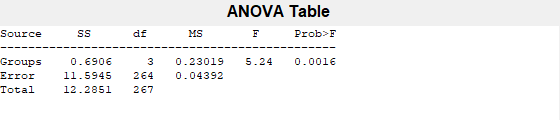

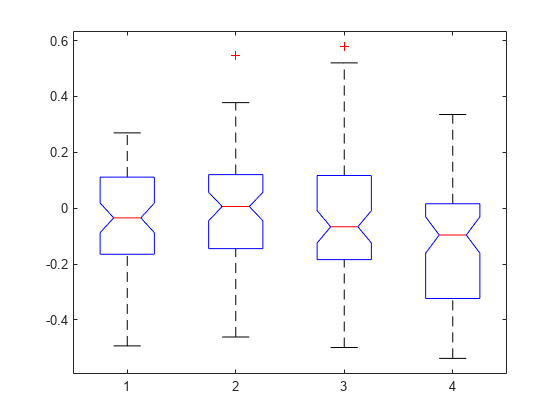

p = 0.0016

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 0.6906]}    {[  3]}    {[  0.2302]}    {[  5.2413]}    {[  0.0016]}
    {'Error' }    {[11.5945]}    {[264]}    {[  0.0439]}    {0×0 double}    {0×0 double}
    {'Total' }    {[12.2851]}    {[267]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [67 67 67 67]
    source: 'anova1'
     means: [-0.0398 -0.0107 -0.0381 -0.1437]
        df: 264
         s: 0.2096


[p,tbl,stats] = anova1(allCorr(:,1), cell2mat(posID))

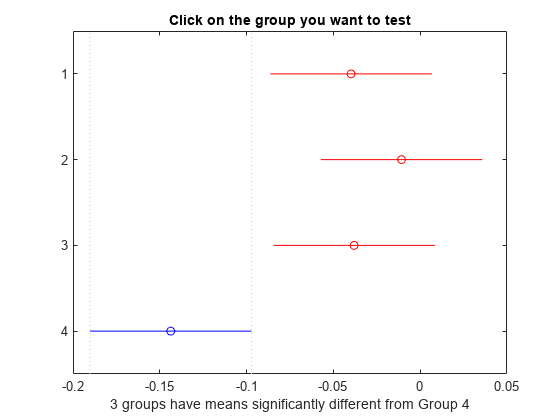

ans =     1.0000    2.0000   -0.1221   -0.0291    0.0640    0.8532
    1.0000    3.0000   -0.0947   -0.0017    0.0913    1.0000
    1.0000    4.0000    0.0109    0.1039    0.1969    0.0214
    2.0000    3.0000   -0.0657    0.0273    0.1204    0.8745
    2.0000    4.0000    0.0399    0.1330    0.2260    0.0014
    3.0000    4.0000    0.0126    0.1056    0.1986    0.0185


figure; multcompare(stats)